defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Figure 3 - ISCs and IHCs']);

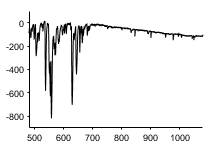

%B
dname = '.\Data\WT_MRS_Blocktail_Control\190508_Cell2';
fileList = loadFileList([dname '\*_gfv.abf']);
[d,~,SR] = loadPclampData(fileList{1});
time = [1:size(d,1)]/SR - 1/SR;

figure; plot(time,d,'Color','k');
xlim([480 1080]);
ylim([-900 100]);
figQuality(gcf,gca,[2.33 1.5]);
export_fig('.\EPS Panels\B_example_MRS_PPADS.eps');

%C
cellS = loadCellStructs('.\Data\WT_MRS_PPADs_RT\*_stats.mat')

cellS = 1×9 struct array with fields:
    rawLocPk
    stats


conditions = {'Baseline','+MRS2500'};

pkstatBlock = [];
ampstatBlock = [];
intstatBlock = [];

for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
end

dim = [1.6 1.6];
h = compare2P(pkstatBlock(:,1),pkstatBlock(:,2),conditions(1:2),'Events per minute',dim,[5 12]);

   4.9101e-06



ylim([0 7.5]);
yticks(0:2.5:7.5);
xtickangle(45);
figQuality(gcf,gca,dim);

h1 = compare2P(ampstatBlock(:,1),ampstatBlock(:,2),conditions(1:2),'Mean amplitude (–pA)',dim,[5 12]);

   2.7210e-04



ylim([0 500]);
yticks(0:250:500);
xtickangle(45);
figQuality(gcf,gca,dim);

h2 = compare2P(intstatBlock(:,1),intstatBlock(:,2),conditions(1:2),'Integral (–pC)',dim,[5 12]);

   3.5039e-04



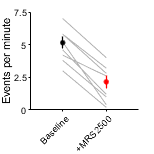

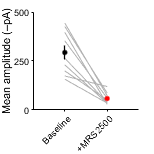

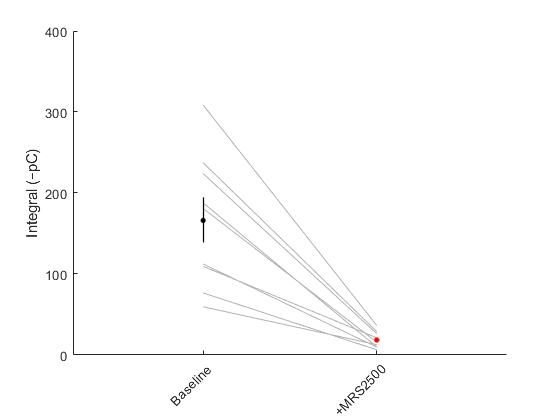

ylim([0 400]);
yticks(0:100:400);
xtickangle(45);

 figh = handleTheSubplot({h, h1, h2}, [1 3]);

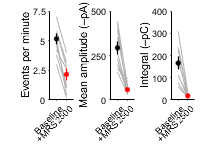

 figQuality(gcf,gca,[2.25 1.5])
 export_fig('.\EPS Panels\RT_summary_stats.eps')

%E
crens = loadCellStructs('.\Data\Crenations\P7_8\*.mat')

crens = 1×8 struct array with fields:
    name
    locs
    pks
    stdStart
    stdEnd
    areas
    meanPlot
    imgSTD
    stdMP
    crenationImg
    scalingFactor



baseline = [0 600-2*60];
MRS2500 = [720 20*60];
freqs = []; areas = [];
for i = 1:size(crens,2)
    freqs(i,:) = [size(crens(i).locs(crens(i).locs < baseline(2)),1)/8 ...
        size(crens(i).locs(crens(i).locs > MRS2500(1)),1)/8];
    areas(i,:) = [nanmean(crens(i).areas(crens(i).locs < baseline(2)),1) ... 
        nanmean(crens(i).areas(crens(i).locs > MRS2500(1)),1) ];
end

figure;
h = compare2P(freqs(:,1),freqs(:,2),{'Baseline','+MRS2500'},'Crenations per minute',[3 2],[5 12]);

    0.0020



xtickangle(45);
ylim([0 4]);
figQuality(gcf,gca,[1.25 1.5]);

figure;
h1 = compare2P(areas(:,1),areas(:,2),{'Baseline','+MRS2500'},'Crenation area ',[3 2],[5 12]);

    0.0098



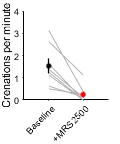

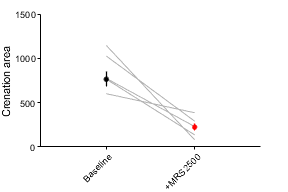

figQuality(gcf,gca,[3 2]);
ylim([0 1500])
xtickangle(45)
handleTheSubplot({h,h1},[1 2]);

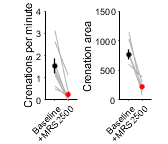

figQuality(gcf,gca,[1.75 1.5])
export_fig('.\EPS Panels\CrenationsFreq_new.eps')

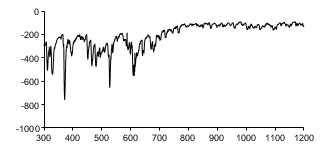

%H
file = '.\Data\WT_Blocktail_MRS\190507_Cell1\19507006_gfv.abf';
[d,time,fs] = loadPclampData(file);
figure; plot(time,lowpass(d,10,fs),'Color','k');
xlim([300 1200]);
ylim([-1000 0]);
figQuality(gcf,gca,[3.5 1.5]);
export_fig('.\EPS Panels\F_Example_MRS_blocktail.eps')

%I
%%load structs
blocktail_cells = loadCellStructs('.\Data\WT_Blocktail_MRS\*\*stats.mat');
MRS_cells = loadCellStructs('.\Data\WT_MRS_Blocktail_Control\*\*stats.mat');
h = compare2([MRS_cells.inwardCurrent]',[blocktail_cells.inwardCurrent]',{'+MRS2500','Blocktail'},'Change in baseline (pA)',[3 2],[5 12]);

   2.6902e-04



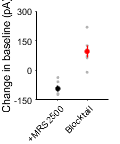

ylim([-150 300]);
yticks([-150:150:300])
xtickangle(45)
figQuality(gcf,gca,[1.25 1.5]);

export_fig('.\EPS Panels\G_Summary_currents.eps');

%H load data
% P6-P8 WT IHC apex MRS application for freq, amp analysis, 6mMK+ external
addpath(genpath('localMatlabFuncs'));
fileList = loadFileList('.\Data\WT_MRS_IHCs_CJK\*bladj.abf')

fileList = 6×1 cell array
    {'M:\Projects and Analysis\Papers\P2ry1\Figure 3 - ISCs and IHCs\Data\WT_MRS_IHCs_CJK\2018_08_22_0005_bladj.abf'}
    {'M:\Projects and Analysis\Papers\P2ry1\Figure 3 - ISCs and IHCs\Data\WT_MRS_IHCs_CJK\2018_08_22_0007_bladj.abf'}
    {'M:\Projects and Analysis\Papers\P2ry1\Figure 3 - ISCs and IHCs\Data\WT_MRS_IHCs_CJK\2018_08_22_0013_bladj.abf'}
    {'M:\Projects and Analysis\Papers\P2ry1\Figure 3 - ISCs and IHCs\Data\WT_MRS_IHCs_CJK\2018_08_28_0011_bladj.abf'}
    {'M:\Projects and Analysis\Papers\P2ry1\Figure 3 - ISCs and IHCs\Data\WT_MRS_IHCs_CJK\2018_08_29_0003_bladj.abf'}
    {'M:\Projects and Analysis\Papers\P2ry1\Figure 3 - ISCs and IHCs\Data\WT_MRS_IHCs_CJK\2018_11_01_0008_bladj.abf'}



[mrs1, time1] = loadPclampData(fileList{1});
[mrs2, time2] = loadPclampData(fileList{2});
[mrs3, time3] = loadPclampData(fileList{3});
[mrs4, time4] = loadPclampData(fileList{4});
[mrs5, time5] = loadPclampData(fileList{5});
[mrs6, time6] = loadPclampData(fileList{6});

[preFreq1,postFreq1,preAmp1,postAmp1] = freqAmpIHC(mrs1,time1,27)

'freqAmpIHC' is not found in the current folder or on the MATLAB path, but exists in:
    M:\Projects and Analysis\Papers\P2ry1\Figure 3 - IHCs\localMatlabFuncs

Change the MATLAB current folder or add its folder to the MATLAB path.

[preFreq2,postFreq2,preAmp2,postAmp2] = freqAmpIHC(mrs2,time2,27)
[preFreq3,postFreq3,preAmp3,postAmp3] = freqAmpIHC(mrs3,time3,22)
[preFreq4,postFreq4,preAmp4,postAmp4] = freqAmpIHC(mrs4,time4,27.5)
[preFreq5,postFreq5,preAmp5,postAmp5] = freqAmpIHC(mrs5,time5,56)
[preFreq6,postFreq6,preAmp6,postAmp6] = freqAmpIHC(mrs6,time6,13)

preMRSFreq = [preFreq1,preFreq2,preFreq3,preFreq4,preFreq5,preFreq6];
postMRSFreq = [postFreq1,postFreq2,postFreq3,postFreq4,postFreq5,postFreq6];

preMRSAmp = abs([preAmp1,preAmp2,preAmp3,preAmp4,preAmp5,preAmp6]);
postMRSAmp = abs([postAmp1,postAmp2,postAmp3,postAmp4,postAmp5,postAmp6]);

## F

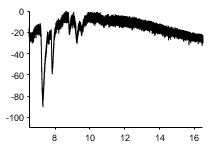

figure;
[mrs1, time1] = loadPclampData('.\Data\WT_MRS_IHCs_CJK\2018_08_22_0007.abf');
timeDrug = 27; %in minutes
newMrs1 = mrs1(time1 >= (timeDrug - 10)*60 & time1 <= (timeDrug + 10)*60);
newTime1 = time1(time1 >= (timeDrug - 10)*60 & time1 <= (timeDrug + 10)*60)/60;
newTime1 = newTime1 - newTime1(1);
plot(newTime1,newMrs1,'Color','k');
xlim([6.5 16.5]);
ylim([-110 0])
figQuality(gcf,gca,[2.33 1.5]);
export_fig('.\EPS Panels\H_exMRSIHC.eps')


conditions = {'baseline','MRS2500'};
ylbl1 = 'Events per minute';
ylbl2 = 'Mean amplitude (-pA)';
dim = [2 3];


%G

%travis modificaitons for figure
conditions = {'Basline','+MRS2500'};
h1 =compare2P(preMRSFreq',postMRSFreq',conditions,ylbl1,dim,[10 12]);

    0.0046



xtickangle(45);
 ylim([0 6]);
 yticks(0:2:6)
 yticklabels({'0','2','4','6'})
 figQuality(gcf,gca,[1.0 1.3])

 %%
h2 =compare2P(preMRSAmp',postMRSAmp',conditions,ylbl2,dim,[10 12]);

    0.0080



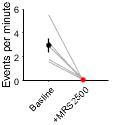

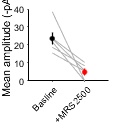

 ylim([0 40]);
 xtickangle(45);
 yticks(0:10:40);
  yticklabels({'0','10','20','30','40'})
 figQuality(gcf,gca,[1.0 1.2])
  figQuality(gcf,gca,[1.0 1.3]) 
handleTheSubplot({h1,h2},[1 2]);

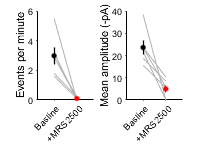

figQuality(gcf,gca,[2.1 1.5]);
export_fig('.\EPS Panels\I_events_amplitude.eps')

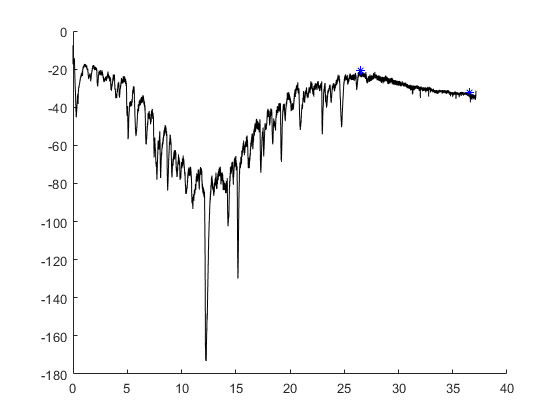

curChange1 = -11.3220

baselineMax1 = -20.8435

endMax1 = -32.1655

%J load data
% P6-P8 WT IHC, apex MRS application, measuring current induction
[mrs1, time1] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_08_22_0005.abf');
[mrs2, time2] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_08_22_0007.abf');
[mrs3, time3] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_08_22_0013.abf');
[mrs4, time4] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_08_28_0011.abf');
[mrs5, time5] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_08_29_0003.abf');
[mrs6, time6] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_11_01_0008.abf');

[acsf1, time1_1] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_08_22_0009.abf');
[acsf2, time2_1] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_08_22_0011.abf');
[acsf3, time3_1] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_08_30_0004.abf');
[acsf4, time4_1] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_08_30_0006.abf');
[acsf5, time5_1] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_10_11_0016.abf');

[mrscs1, time1cs] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_09_13_0002.abf');
[mrscs2, time2cs] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_09_13_0006.abf');
[mrscs3, time3cs] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_09_24_0005.abf');
[mrscs4, time4cs] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_10_04_0000.abf');
[mrscs5, time5cs] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_10_04_0002.abf');
[mrscs6, time6cs] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_10_04_0003.abf');

[acsfcs1, time1_2] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_09_21_0000.abf');
[acsfcs2, time2_2] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_09_21_0001.abf');
[acsfcs3, time3_2] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_09_21_0002.abf');
[acsfcs4, time4_2] = loadPclampData('.\Data\WT_CsCl_AllExperiments\2018_10_04_0005.abf');

% change in holding current analysis

[curChange1,baselineMax1,endMax1] = currentAnalysisIHC(mrs1,time1,26.5,10)

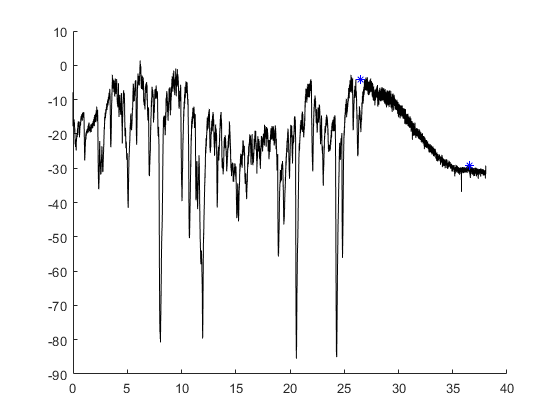

curChange2 = -25.1465

baselineMax2 = -4.1199

endMax2 = -29.2664

[curChange2,baselineMax2,endMax2] = currentAnalysisIHC(mrs2,time2,26.5,10)

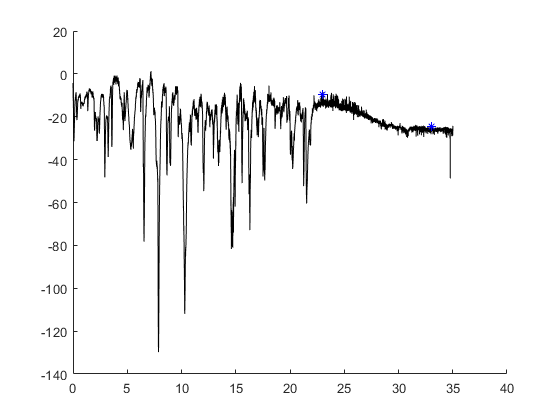

curChange3 = -15.0452

baselineMax3 = -9.4910

endMax3 = -24.5361

[curChange3,baselineMax3,endMax3] = currentAnalysisIHC(mrs3,time3,23,10)

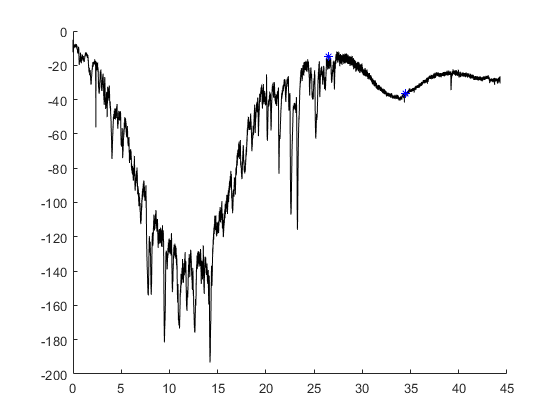

curChange4 = -21.2402

baselineMax4 = -15.1062

endMax4 = -36.3464

[curChange4,baselineMax4,endMax4] = currentAnalysisIHC(mrs4,time4,26.5,8)

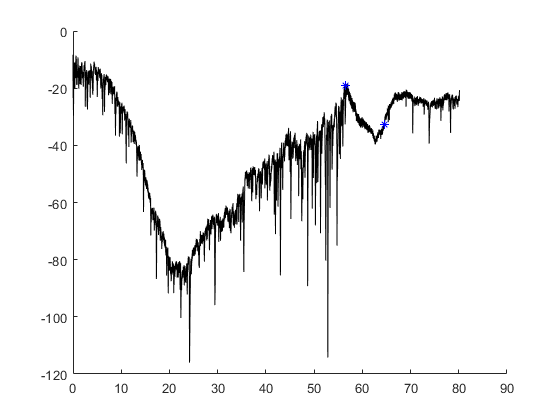

curChange5 = -13.5498

baselineMax5 = -19.1040

endMax5 = -32.6538

[curChange5,baselineMax5,endMax5] = currentAnalysisIHC(mrs5,time5,56.5,8)

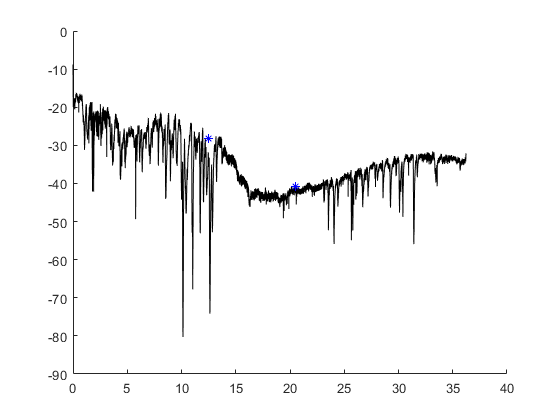

curChange6 = -12.5732

baselineMax6 = -28.3203

endMax6 = -40.8936

[curChange6,baselineMax6,endMax6] = currentAnalysisIHC(mrs6,time6,12.5,8)

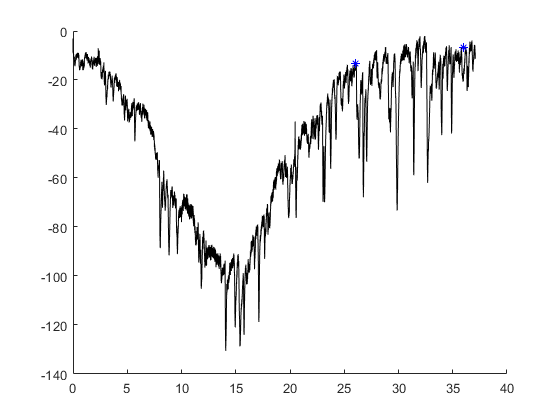

curChangeACSF1 = 6.3629

baselineMaxACSF1 = -13.1073

endMaxACSF1 = -6.7444


curChangeMRS = [curChange1,curChange2,curChange3,curChange4,curChange5,curChange6];
baselineMaxMRS = [baselineMax1,baselineMax2,baselineMax3,baselineMax4,baselineMax5,baselineMax6];
endMaxMRS = [endMax1,endMax2,endMax3,endMax4,endMax5,endMax6];

[curChangeACSF1,baselineMaxACSF1,endMaxACSF1] = currentAnalysisIHC(acsf1,time1_1,26,10)

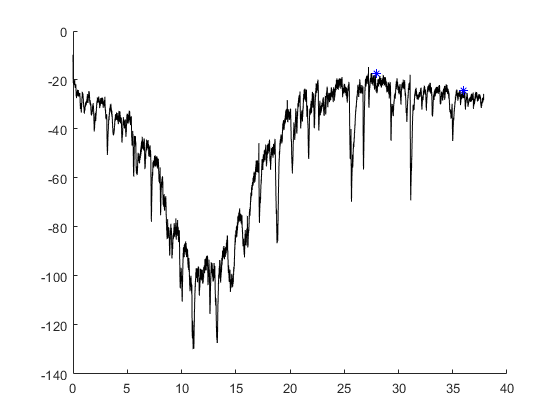

curChangeACSF2 = -7.0496

baselineMaxACSF2 = -17.1814

endMaxACSF2 = -24.2310

[curChangeACSF2,baselineMaxACSF2,endMaxACSF2] = currentAnalysisIHC(acsf2,time2_1,28,8)

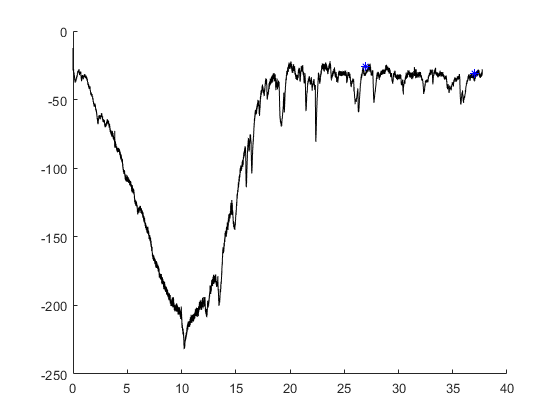

curChangeACSF3 = -4.6997

baselineMaxACSF3 = -26.0620

endMaxACSF3 = -30.7617

[curChangeACSF3,baselineMaxACSF3,endMaxACSF3] = currentAnalysisIHC(acsf3,time3_1,27,10)

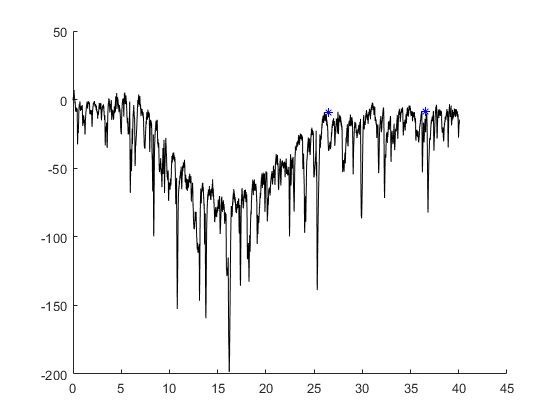

curChangeACSF4 = 0.3662

baselineMaxACSF4 = -9.0942

endMaxACSF4 = -8.7280

[curChangeACSF4,baselineMaxACSF4,endMaxACSF4] = currentAnalysisIHC(acsf4,time4_1,26.5,10)

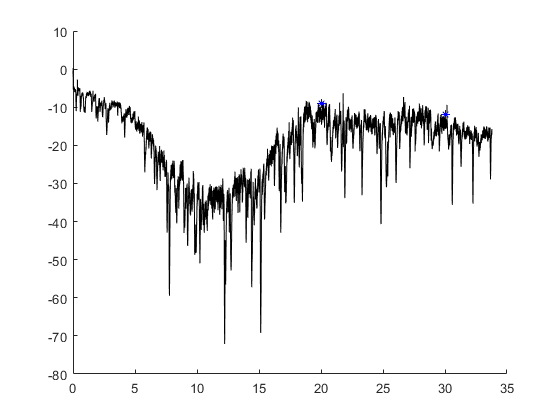

curChangeACSF5 = -3.0212

baselineMaxACSF5 = -8.9111

endMaxACSF5 = -11.9324

[curChangeACSF5,baselineMaxACSF5,endMaxACSF5] = currentAnalysisIHC(acsf5,time5_1,20,10)

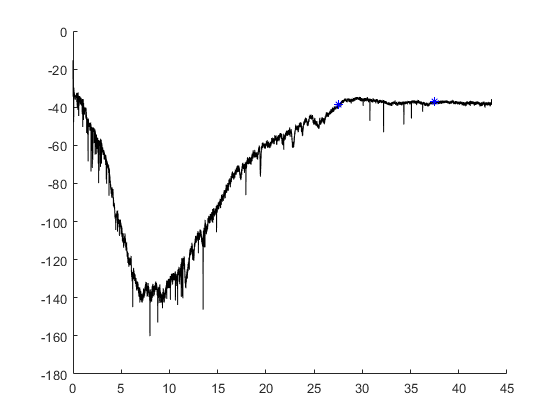

curChange1cs = 2.0599

baselineMax1cs = -38.8031

endMax1cs = -36.7432


curChangeACSF = [curChangeACSF1,curChangeACSF2,curChangeACSF3,curChangeACSF4,curChangeACSF5];
baselineMaxACSF = [baselineMaxACSF1,baselineMaxACSF2,baselineMaxACSF3,baselineMaxACSF4,baselineMaxACSF5];
endMaxACSF = [endMaxACSF1,endMaxACSF2,endMaxACSF3,endMaxACSF4,endMaxACSF5];

[curChange1cs,baselineMax1cs,endMax1cs] = currentAnalysisIHC(mrscs1,time1cs,27.5,10)

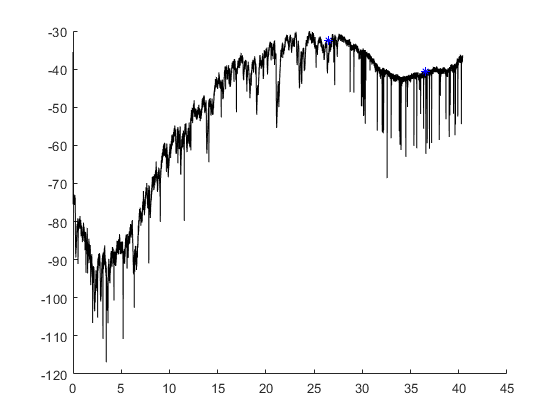

curChange2cs = -7.8735

baselineMax2cs = -32.6233

endMax2cs = -40.4968

[curChange2cs,baselineMax2cs,endMax2cs] = currentAnalysisIHC(mrscs2,time2cs,26.5,10)

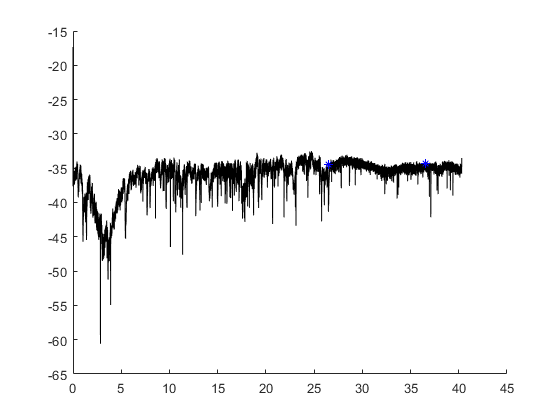

curChange3cs = 0.1221

baselineMax3cs = -34.3933

endMax3cs = -34.2712

[curChange3cs,baselineMax3cs,endMax3cs] = currentAnalysisIHC(mrscs3,time3cs,26.5,10)

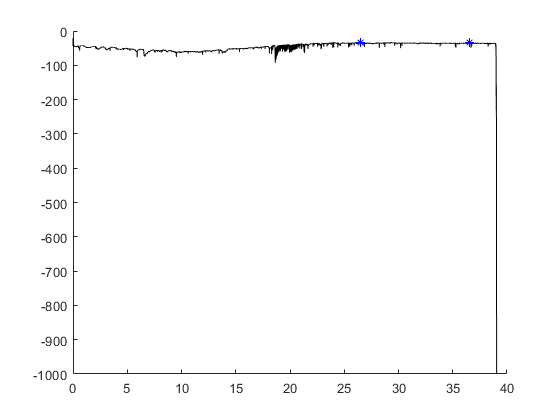

curChange4cs = -1.2512

baselineMax4cs = -33.2031

endMax4cs = -34.4543

[curChange4cs,baselineMax4cs,endMax4cs] = currentAnalysisIHC(mrscs4,time4cs,26.5,10)

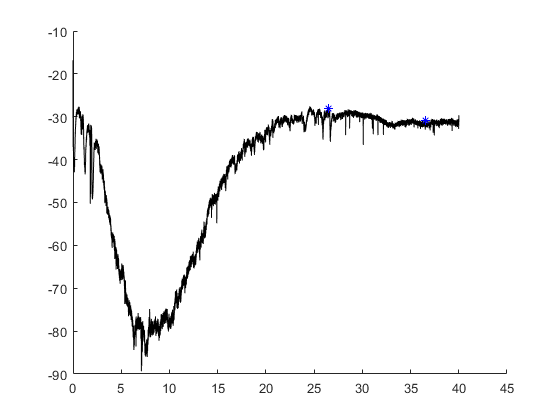

curChange5cs = -2.7008

baselineMax5cs = -28.0762

endMax5cs = -30.7770

[curChange5cs,baselineMax5cs,endMax5cs] = currentAnalysisIHC(mrscs5,time5cs,26.5,10)

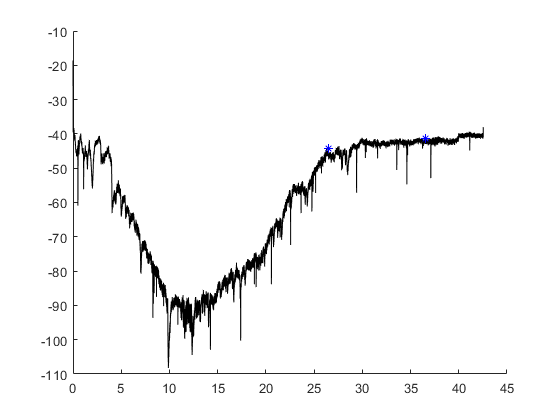

curChange6cs = 2.8839

baselineMax6cs = -44.2963

endMax6cs = -41.4124

[curChange6cs,baselineMax6cs,endMax6cs] = currentAnalysisIHC(mrscs6,time6cs,26.5,10)

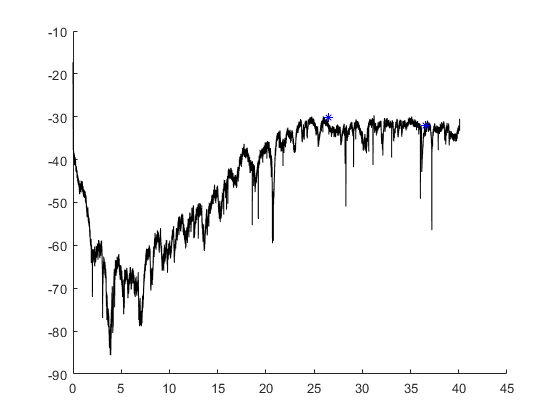

curChangeACSFcs1 = -1.8311


curChangeMRScs = [curChange1cs,curChange2cs,curChange3cs,curChange4cs,curChange5cs,curChange6cs];
baselineMaxcs = [baselineMax1cs,baselineMax2cs,baselineMax3cs,baselineMax4cs,baselineMax5cs,baselineMax6cs];
endMaxcs = [endMax1cs,endMax2cs,endMax3cs,endMax4cs,endMax5cs,endMax6cs];

[curChangeACSFcs1] = currentAnalysisIHC(acsfcs1,time1_2,26.5,10)

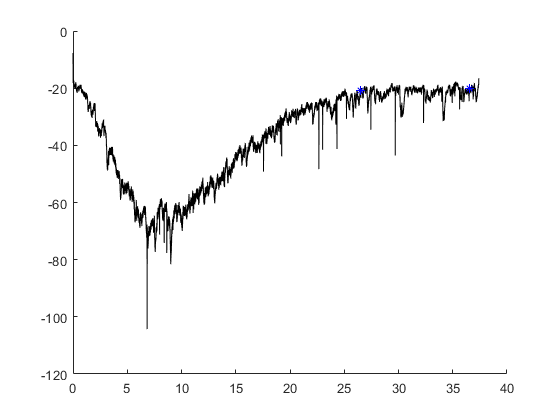

curChangeACSFcs2 = 0.4730

[curChangeACSFcs2] = currentAnalysisIHC(acsfcs2,time2_2,26.5,10)

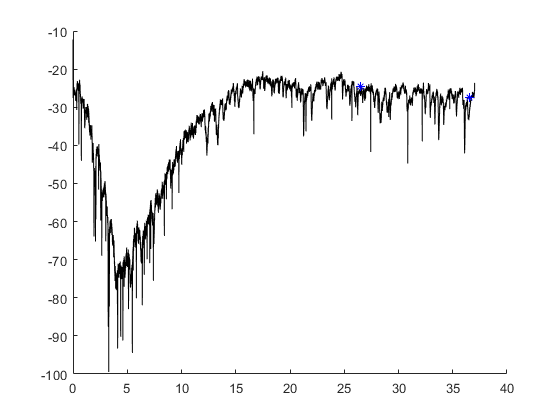

curChangeACSFcs3 = -2.9297

[curChangeACSFcs3] = currentAnalysisIHC(acsfcs3,time3_2,26.5,10)

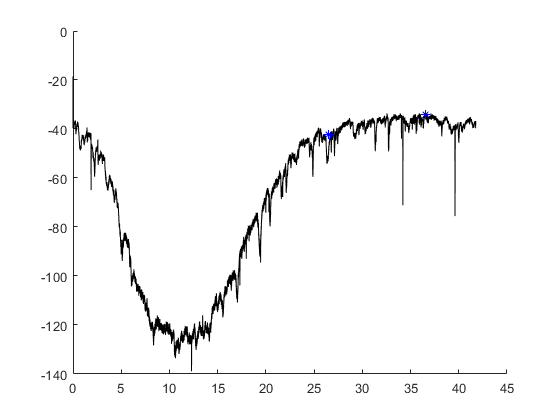

curChangeACSFcs4 = 8.2092

[curChangeACSFcs4] = currentAnalysisIHC(acsfcs4,time4_2,26.5,10)

curChangeACSFcs =    -1.8311    0.4730   -2.9297    8.2092


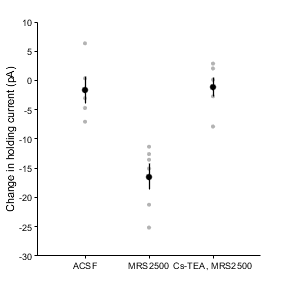


curChangeACSFcs = [curChangeACSFcs1,curChangeACSFcs2,curChangeACSFcs3,curChangeACSFcs4]

%K
figure
mrscs3 = medfilt1(mrscs3,200);
plot(time3cs/60,mrscs3(),'k','LineWidth',2)
ylim([-110 0])
xlim([20 35])
figQuality(gcf,gca,[3.5 1.5])
export_fig('.\EPS Panels\J_cs_example.eps')


conditions = {'+aCSF','+MRS2500','+aCSF','+MRS2500'};
h = compare4_2(curChangeACSF,curChangeMRS,curChangeACSFcs,curChangeMRScs,conditions,ylbl,dim,[5 12])

p = 5.1621e-05

stats = struct with fields:
    gnames: {4×1 cell}
         n: [5 6 4 6]
    source: 'anova1'
     means: [-1.6083 -16.4795 0.9804 -1.1266]
        df: 17
         s: 4.9134


c =     1.0000    2.0000    6.4141   14.8712   23.3284    0.0006
    1.0000    3.0000  -11.9577   -2.5887    6.7804    0.8600
    1.0000    4.0000   -8.9388   -0.4817    7.9755    0.9984
    2.0000    3.0000  -26.4752  -17.4599   -8.4445    0.0002
    2.0000    4.0000  -23.4164  -15.3529   -7.2893    0.0002
    3.0000    4.0000   -6.9084    2.1070   11.1223    0.9090


gnames = 4×1 cell array
    {'ACSF'  }
    {'MRS'   }
    {'ACSFcs'}
    {'MRScs' }


h =   Figure (218) with properties:

      Number: 218
        Name: ''
       Color: [1 1 1]
    Position: [0 0 3 3]
       Units: 'inches'

  Show all properties


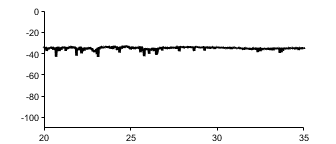

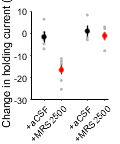

ylim([-30 10])
figQuality(gcf,gca,[1.25 1.5])
export_fig('.\EPS Panels\K_inward_currents.eps')